# 案例：用 Matlab 绘制高质量的论文插图

此案例演示如何用 Matlab 绘制常见的高质量论文插图：

- 二维曲线图、散点图、渐变色图、条形图、填充图、多 Y 轴图、二维场图、带箭头曲线；

- 三维曲线图、散点图、伪彩图、裁剪伪彩图、等高线图、等高线填充图、矢量场图；

clear;clc;close all;

## 二维曲线

二维曲线算是最最常见的一种曲线了，它能反应两个变量的因果关系；

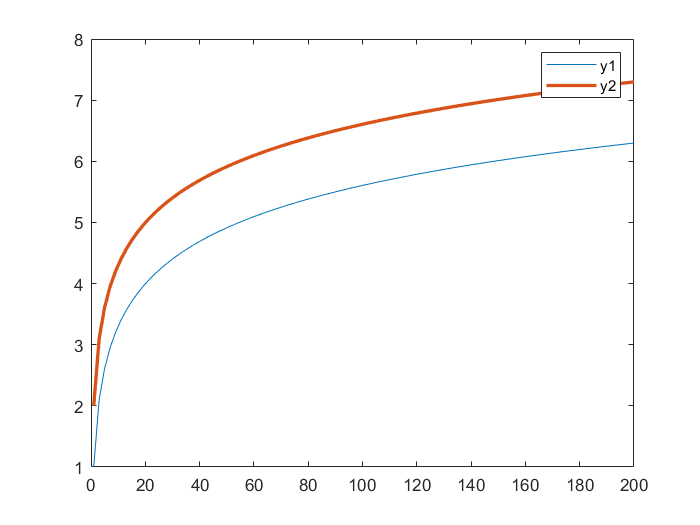

x = linspace(1, 200, 100);
y1 = log(x) + 1;
y2 = log(x) + 2;
figure;
plot(x, y1);
hold on
plot(x, y2, 'LineWidth', 2);
hold off
legend('y1', 'y2');

调整线的粗细，给人感觉就不一样；

或者说这个颜色可能你觉得不好看，查阅帮助文档里给的的标准颜色也都不喜欢，没关系，我整理了 28 种个人觉得比较好看的颜色，自行做一下颜色搭配，一般够用了；

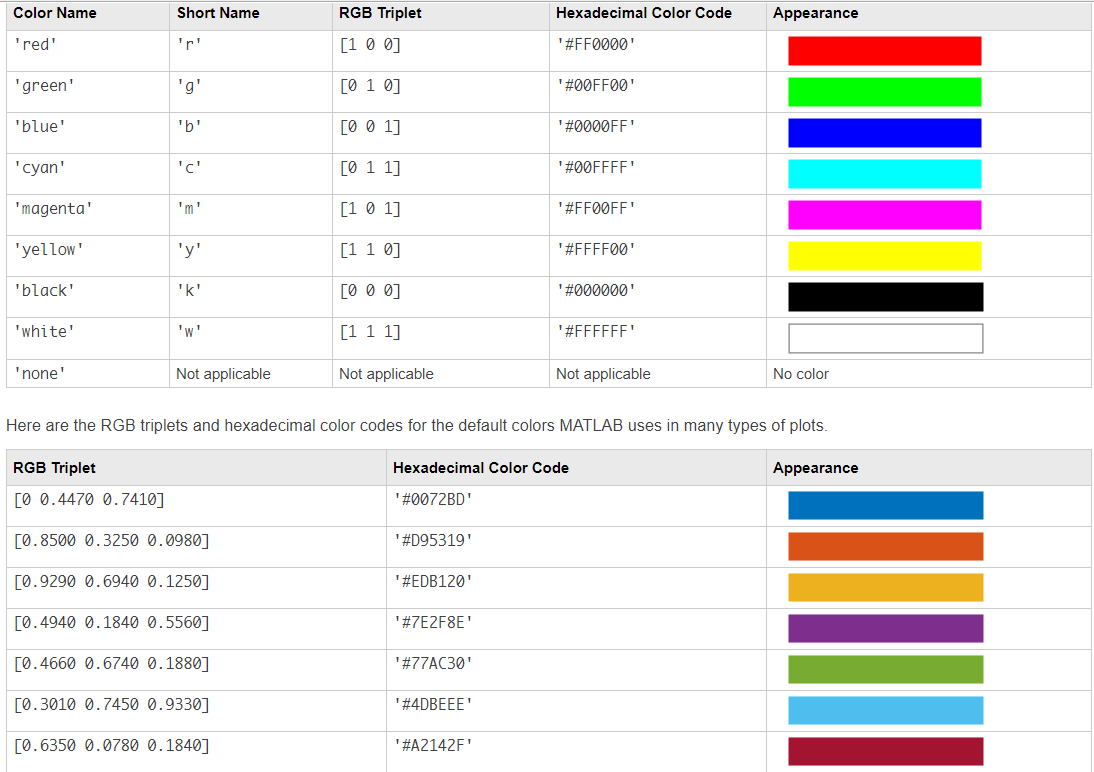

[https://zhuanlan.zhihu.com/p/444970597](https://zhuanlan.zhihu.com/p/444970597)

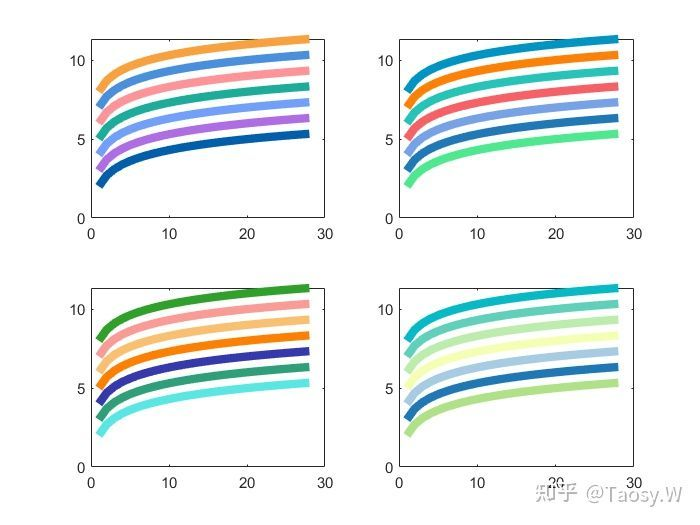

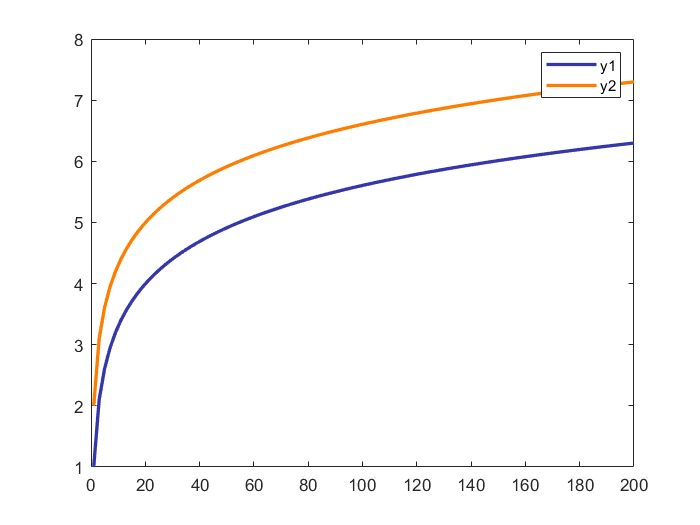

figure;
plot(x, y1, 'LineWidth', 2, 'Color', [0.21, 0.21, 0.67]);
hold on
plot(x, y2, 'LineWidth', 2, 'Color', [0.99, 0.49, 0.00]);
hold off
legend('y1', 'y2');

## 二维散点图

常用来比较理论数据和实验数据的趋势关系；

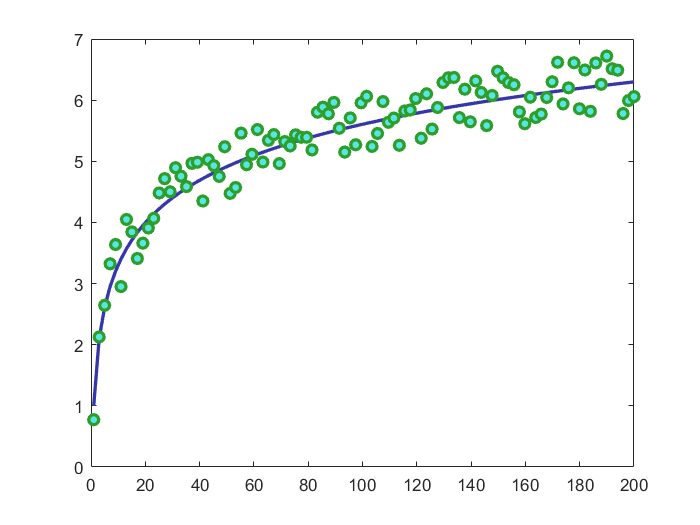

figure;
y3 = y1 + rand(1, 100) - 0.5;
plot(x, y1, 'LineWidth', 2, 'Color', [0.21, 0.21, 0.67]);
hold on
% 设置数据点的形状、数据点的填充颜色、数据点的轮廓颜色
plot(x, y3, 'o', 'LineWidth', 2, 'Color', [0.46, 0.63, 0.90], 'MarkerFaceColor', [0.35, 0.90, 0.89], 'MarkerEdgeColor', [0.18, 0.62, 0.17]);
hold off

## 渐变色图

用不同的颜色、数据点大小表征不同数值，更加直观；

更详细的案例分析：[https://zhuanlan.zhihu.com/p/404594879](https://zhuanlan.zhihu.com/p/404594879)

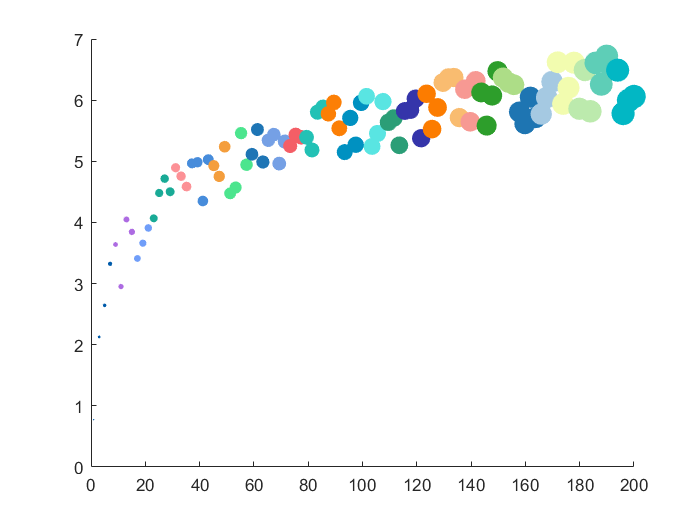

% 先自己做一个 colormap
c_map =  [0.00, 0.36, 0.67
          0.68, 0.42, 0.89
          0.44, 0.62, 0.98
          0.10, 0.67, 0.59
          0.99, 0.57, 0.59
          0.28, 0.55, 0.86
          0.96, 0.62, 0.24
          0.30, 0.90, 0.56
          0.12, 0.46, 0.71
          0.46, 0.63, 0.90
          0.96, 0.37, 0.40
          0.14, 0.76, 0.71
          0.99, 0.50, 0.02
          0.00, 0.57, 0.76
          0.35, 0.90, 0.89
          0.17, 0.62, 0.47
          0.21, 0.21, 0.67
          0.99, 0.49, 0.00
          0.98, 0.74, 0.44
          0.97, 0.60, 0.58
          0.18, 0.62, 0.17
          0.68, 0.87, 0.53
          0.12, 0.46, 0.70
          0.65, 0.79, 0.89
          0.95, 0.99, 0.69
          0.74, 0.92, 0.68
          0.37, 0.81, 0.72
          0.01, 0.72, 0.77];
scatter(x, y3, x, x, 'filled');
colormap(c_map);

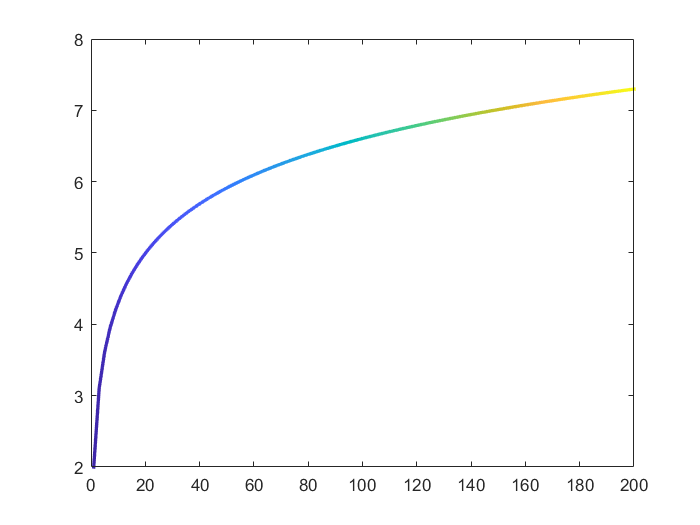

figure;
fill([x, NaN], [y2, NaN], [x, NaN], 'EdgeColor', 'interp', 'LineWidth', 2);

## 条形图

正常条形图没啥好说的，这里演示绘制带有误差线的柱状图：

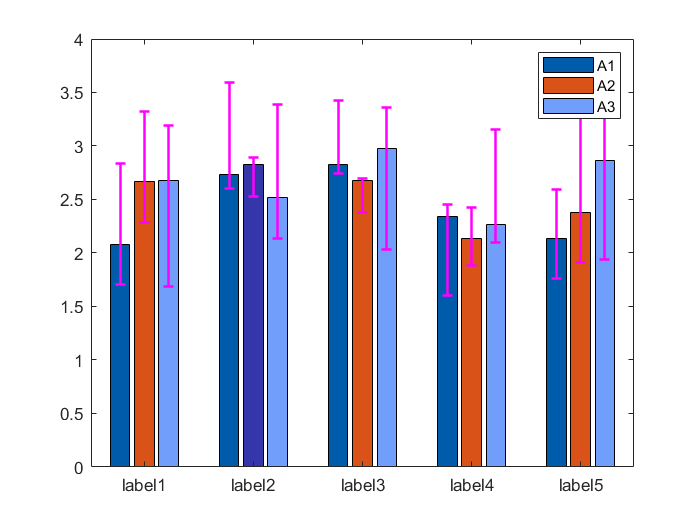

figure;
m = 5;
n = 3;
x = 1:m;
y = rand(m, n) + 2;
% 误差限
neg = rand(m, n);
pos = rand(m, n);
% 绘制柱状图
h = bar(x, y);
% 设置三个系列颜色
h(1, 1).FaceColor = [0.00, 0.36, 0.67];
h(1, 2).FaceColor = [0.68, 0.42, 0.89];
h(1, 3).FaceColor = [0.44, 0.62, 0.98];
% 单独设置第二个系列第二个柱子颜色
h(1, 2).FaceColor = 'flat';
h(1, 2).CData(2,:) = [0.21, 0.21, 0.67]; 
% 获取误差线 x 值
xx = zeros(m, n);
for i = 1 : n
    xx(:, i) = h(1, i).XEndPoints'; 
end
% 绘制误差线
hold on
errorbar(xx, y, neg, pos, 'LineStyle', 'none', 'Color', 'm', 'LineWidth', 1.5);
hold off
% 绘制图例
legend({'A1', 'A2', 'A3'});
% 设置 x 轴标签
set(gca, 'XTickLabel', {'label1', 'label2', 'label3', 'label4', 'label5'});

## 填充图

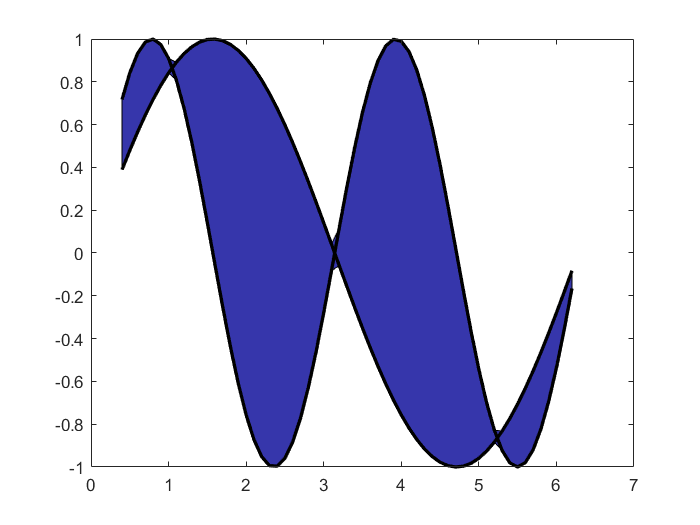

x = 0.4:0.1:2*pi;
y1 = sin(2*x);
y2 = sin(x);
% 确定 y1 和 y2 的上下边界
maxY = max([y1; y2]);
minY = min([y1; y2]);
% 确定填充多边形，按照顺时针方向来确定点
% fliplr 实现左右翻转
xFill = [x, fliplr(x)];
yFill = [maxY, fliplr(minY)];
figure
fill(xFill, yFill, [0.21, 0.21, 0.67]);
hold on
% 绘制轮廓线
plot(x, y1, 'k', 'LineWidth', 2)
plot(x, y2, 'k', 'LineWidth', 2)
hold off

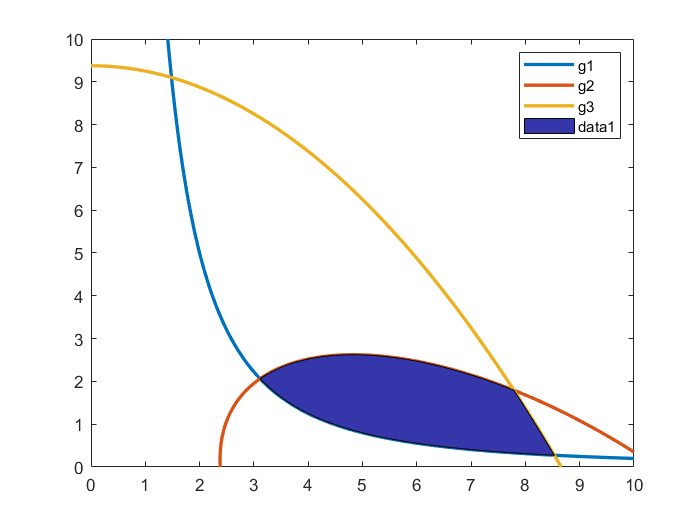

% 函数交叉区域填充
figure;
% 这是三个方程
g1 = @(x,y) 1 - x.^2.*y/20;
g2 = @(x, y) 1 - (x+y-5).^2/30 - (x-y-12).^2/120;
g3 = @(x, y) 1 - 80./(x.^2 + 8*y + 5);
% 把他们的图像画出来
h1 = fimplicit(g1, [0, 10], 'LineWidth', 2);
hold on
h2 = fimplicit(g2, [0, 10], 'LineWidth', 2);
h3 = fimplicit(g3, [0, 10], 'LineWidth', 2);
legend('g1', 'g2', 'g3');
% 问题来了，这个 y 值怎么确定
x1 = h1.XData;
y1 = h1.YData;
x2 = h2.XData;
y2 = h2.YData;
x3 = h3.XData;
y3 = h3.YData;
% 发现 x1, x2 是从大到小的，逆序搞一下
x1 = fliplr(x1);
x2 = fliplr(x2);
y1 = fliplr(y1);
y2 = fliplr(y2);
% 接下来，确定相交区域，主要看这三个关键点：g1-g2, g1-g3, g2-g3
% 数据长度不一样，难搞了，借助【数据提示】功能吧
pt1 = [3.11069, 2.06667];
pt2 = [8.53623, 0.266667];
pt3 = [7.7847, 1.8];
% 确定三个范围
idx1 = find(x1 >= pt1(1) & x1 < pt2(1));
idx2 = find(x2 >= pt1(1) & x2 < pt3(1));
idx3 = find(x3 >= pt3(1) & x3 < pt2(1));
x1 = x1(idx1);
x2 = x2(idx2);
x3 = x3(idx3);
y1 = y1(idx1);
y2 = y2(idx2);
y3 = y3(idx3);
% 一定要是一个闭环
xFill = [x1, fliplr(x3), fliplr(x2)];
yFill = [y1, fliplr(y3), fliplr(y2)];
fill(xFill, yFill, [0.21, 0.21, 0.67]);
hold off

## 多 Y 轴图

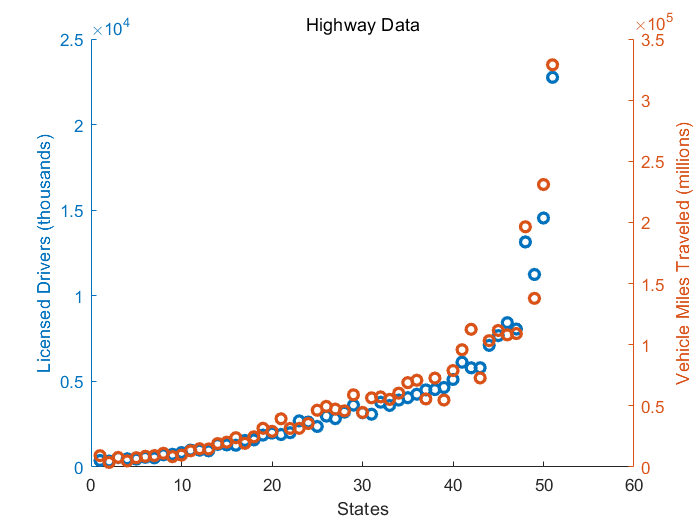

figure;
load('accidents.mat','hwydata')
ind = 1:51;
drivers = hwydata(:,5);
yyaxis left
scatter(ind, drivers, 'LineWidth', 2);
title('Highway Data');
xlabel('States');
ylabel('Licensed Drivers (thousands)');
pop = hwydata(:,7);
yyaxis right
scatter(ind, pop, 'LineWidth', 2);
ylabel('Vehicle Miles Traveled (millions)');

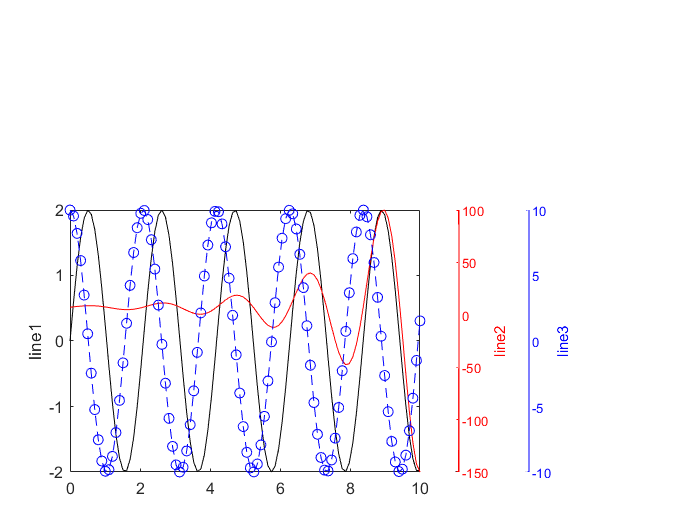

figure;
x = linspace(0,10);
y1 = 2*sin(3*x);
y2 = sin(3*x).*exp(0.5*x);
%% 三个纵坐标演示，更多纵坐标可以按照此方法类推
y3 = 10*cos(3*x);
% 控制 aies 的大小和位置，注意是相对于figure的，范围为[0, 1]
% 三条线绘制到一起，注意数据都标准化到 y1 范围
maxY1 = max(y1);
maxY2 = max(y2);
maxY3 = max(y3);
minY1 = min(y1);
minY2 = min(y2);
minY3 = min(y3);
newY2 = (y2 - minY2)/(maxY2 - minY2);   % 归一化
newY2 = newY2*(maxY1 - minY1) + minY1;  % 反归一化
newY3 = (y3 - minY3)/(maxY3 - minY3);
newY3 = newY3*(maxY1 - minY1) + minY1;
% 画线
axes('position', [0.1 0.1 0.5 0.5]);   
plot(x, y1, 'k', x, newY2, 'r', x, newY3, 'ob--')
ylabel('line1');
% 绘制另外两个空的坐标轴
h2 = axes('position', [0.65 0.1 0.005 0.5]); 
% 重复绘制，曲线颜色用白色，和figure背景色一致，看不出来即可
plot(x, y2, 'w')
% 颜色，位置，曲线标签
set(h2, 'ycolor', 'r', 'yaxislocation', 'right', 'xtick', [])
% 不知道为啥2018B版本边界显示不清楚，所以画一条线
hold on
limX2 = get(h2, 'Xlim');
limY2 = get(h2, 'Ylim');
plot([limX2(2), limX2(2)], limY2, 'r');
hold off
% 取消边框
box off
ylabel('line2');
%
h3 = axes('position', [0.75 0.1 0.005 0.5]); 
plot(x, y3, 'w')
set(h3, 'ycolor', 'b', 'yaxislocation', 'right', 'xtick', [])
hold on
limX3 = get(h3, 'Xlim');
limY3 = get(h3, 'Ylim');
plot([limX3(2), limX3(2)], limY3, 'b');
hold off
box off
ylabel('line3');

% 取消坐标轴的颜色，和figure统一
% set(h1, 'color','none')
% set(h2, 'color','none')
% set(h3, 'color','none')
% figure背景设置成白色
set(gcf,'color','white');  

## 带箭头曲线

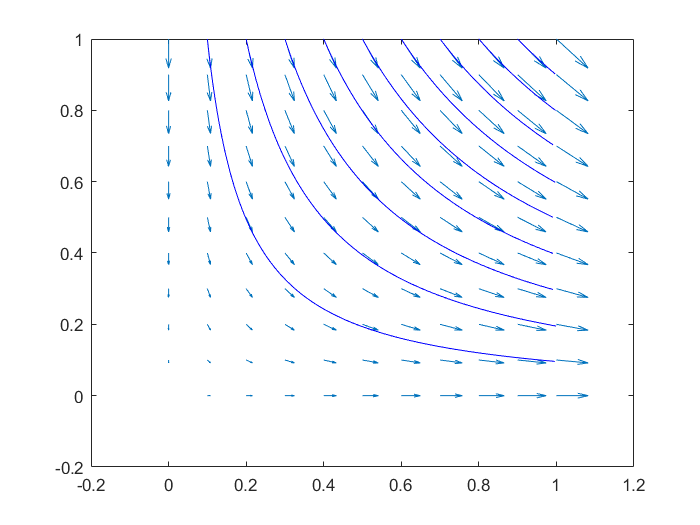

% 直接把 streamline 函数的帮助文档 demo 拷贝过来 
[x, y] = meshgrid(0:0.1:1, 0:0.1:1);
u = x;
v = -y;
startx = 0.1:0.1:0.9;
starty = ones(size(startx));
% 需要获取所有流线的属性
figure;
quiver(x, y, u, v);
streamline(x, y, u, v, startx, starty);

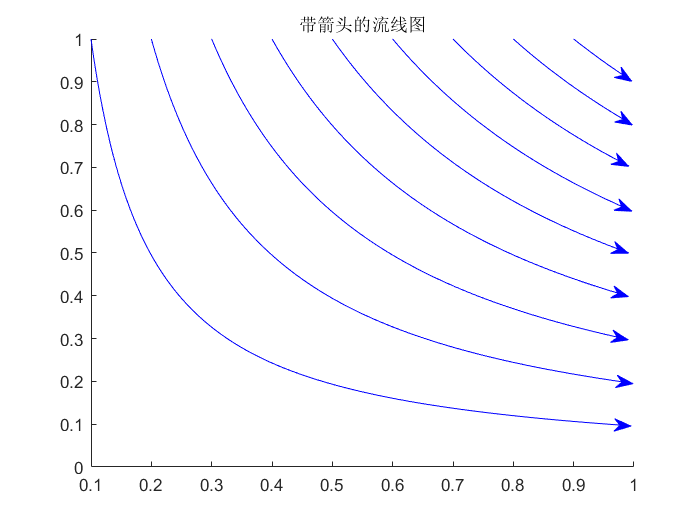

figure;
lines = streamline(x, y, u, v, startx, starty);
% 下面开始画箭头，涉及到坐标的转换
% 获取 Axes 位置
posAxes = get(gca, 'Position');
posX = posAxes(1);
posY = posAxes(2);
width = posAxes(3);
height = posAxes(4);
% 获取 Axes 范围
limX = get(gca, 'Xlim');
limY = get(gca, 'Ylim');
minX = limX(1);
maxX = limX(2);
minY = limY(1);
maxY = limY(2);
% 遍历，逐条流线加箭头
for i = 1 : length(lines)
    % 获取每条流线的数据
    xData = lines(i).XData;
    yData = lines(i).YData;
    % 这里取的是最后两个点，一定要是相邻的两个点用来确定箭头方向
    x0 = xData(end-1 : end);
    y0 = yData(end-1 : end);
    % 转换坐标到相对于figure的坐标
    xNew = posX + (x0 - minX) / (maxX - minX) * width;
    yNew = posY + (y0 - minY) / (maxY - minY) * height;
    % 画箭头
    hold on
    annotation('arrow', xNew, yNew, 'color', 'b');
end
hold off
title('带箭头的流线图');

## 三维曲线图

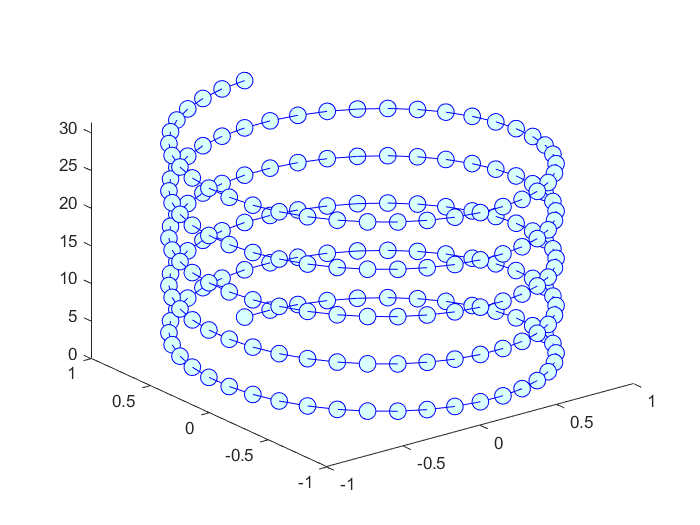

figure;
t = 0:pi/20:10*pi;
xt = sin(t);
yt = cos(t);
plot3(xt, yt, t, '-o', 'Color', 'b', 'MarkerSize', 10, 'MarkerFaceColor', '#D9FFFF');

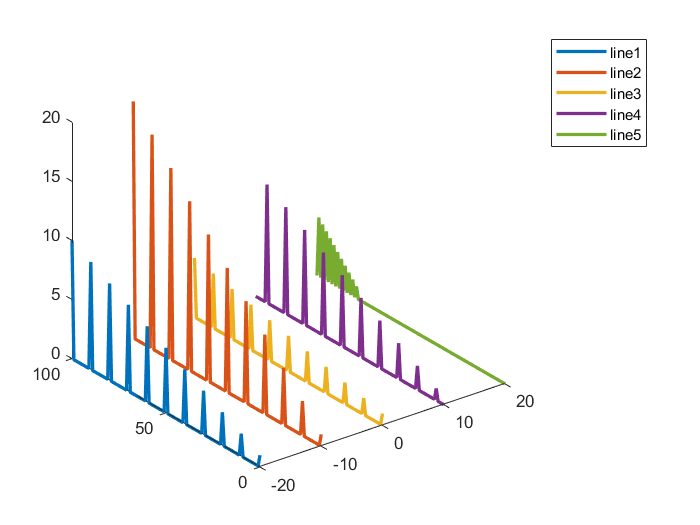

figure;
x = -20:10:20;
y = 0:100;
% 随便生成的 5 组数据，也就是目标图上的 5 条曲线数据
z = zeros(5, 101);
z(1, 1:10:end) = linspace(1, 10, 11);
z(2, 1:10:end) = linspace(1, 20, 11);
z(3, 1:10:end) = linspace(1, 5, 11);
z(4, 5:10:end) = linspace(1, 10, 10);
z(5, 80:2:end) = linspace(1, 5, 11);
for i = 1:5
    % x 方向每条曲线都是一个值，重复 y 的长度这么多次 
    xx = x(i)*ones(1, 101);
    % z 方向的值，每次取一条
    zz = z(i, :);
    % plot3 在 xyz 空间绘制曲线，保证 x y z 长度一致即可
    plot3(xx, y, zz, 'LineWidth', 2);
    hold on
end
hold off
legend('line1', 'line2', 'line3', 'line4', 'line5');

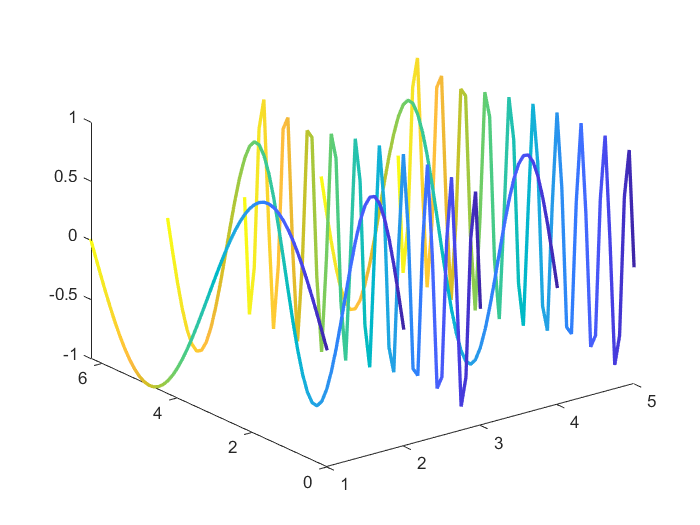

% 如果把渐变曲线和三维曲线结合起来
figure;
x = linspace(0, 2*pi, 50);
y = sin(x);
fill3([ones(size(x)), NaN], [x, NaN], [y, NaN], [x NaN], 'EdgeColor', 'interp', 'LineWidth', 2)
hold on
for i = 2 : 5
    if mod(i, 2) == 0
        y = sin(2*x);
        fill3([i * ones(size(x)), NaN], [x, NaN], [y, NaN], [x NaN], 'EdgeColor', 'interp', 'LineWidth', 2)
    else
        y = sin(10*x);
        fill3([i * ones(size(x)), NaN], [x, NaN], [y, NaN], [x NaN], 'EdgeColor', 'interp', 'LineWidth', 2)
    end
end
hold off

## 三维散点图

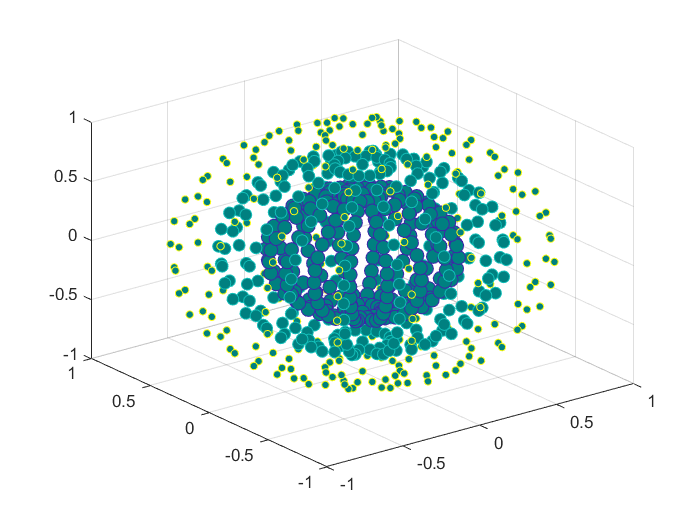

figure;
[X,Y,Z] = sphere(16);
x = [0.5*X(:); 0.75*X(:); X(:)];
y = [0.5*Y(:); 0.75*Y(:); Y(:)];
z = [0.5*Z(:); 0.75*Z(:); Z(:)];
S = repmat([70, 50, 20],numel(X), 1);
C = repmat([1, 2, 3], numel(X), 1);
s = S(:);
c = C(:);
h = scatter3(x, y, z, s, c);
h.MarkerFaceColor = [0 0.5 0.5];

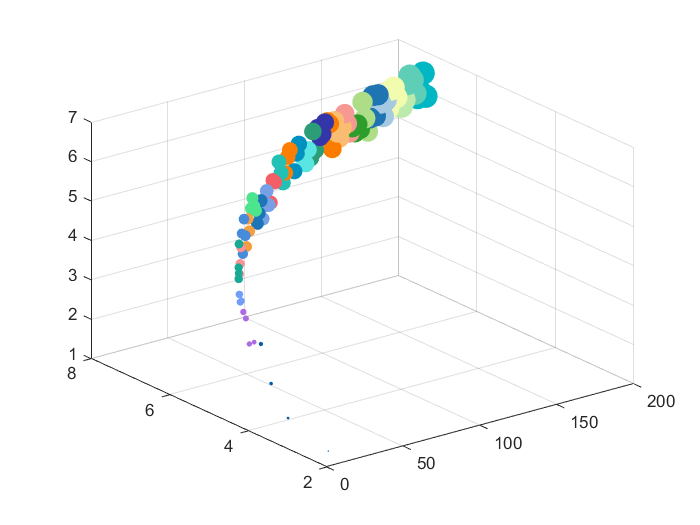

x = linspace(1, 200, 100);
y1 = log(x) + 1;
y2 = log(x) + 2;
y3 = y1 + rand(1, 100) - 0.5;
figure;
scatter3(x, y2, y3, x, x, 'filled');
colormap(c_map);

## 三维伪彩图

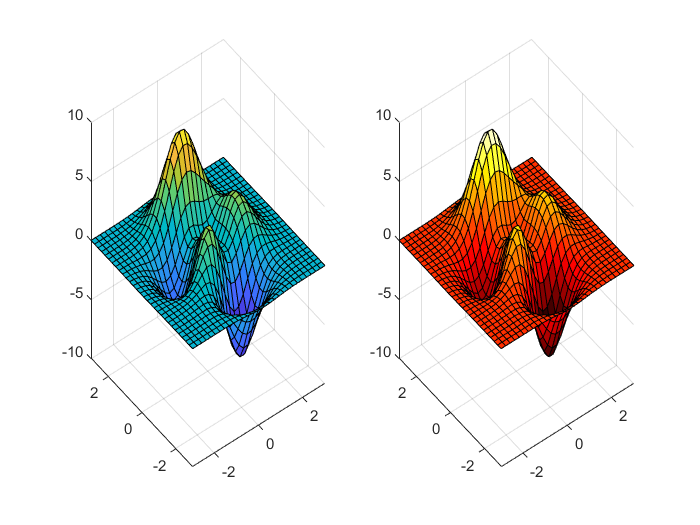

[x, y, z] = peaks(30);
figure;
plot1 = subplot(1,2,1);
surf(x, y, z);
% 获取第一幅图的 colormap，默认为 parula
cMap = colormap;
plot2 = subplot(1,2,2);
surf(x, y, z);
% 下面设置的是第二幅图的颜色，默认是整个 figure 的
colormap(hot);
% 设置第一幅图颜色显示为 parula
set(plot1, 'Colormap', cMap);

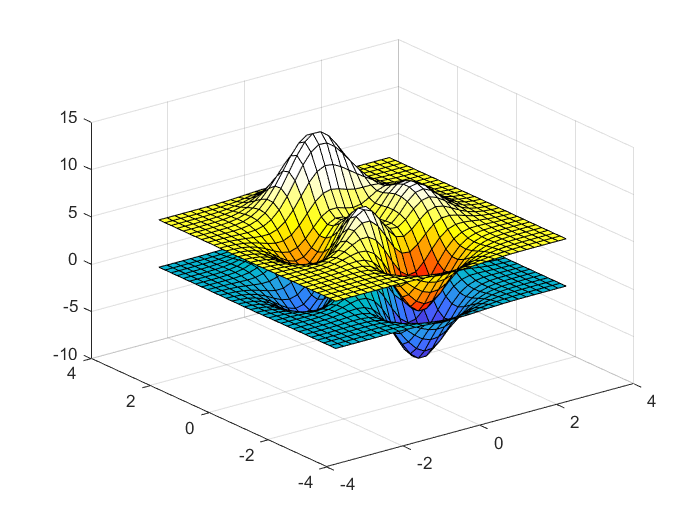

% 一个坐标轴
figure;
h1 = surf(x, y, z);
freezeColors;
hold on
h2 = surf(x, y, z + 5);
hold off
colormap(hot);

## 裁剪伪彩图

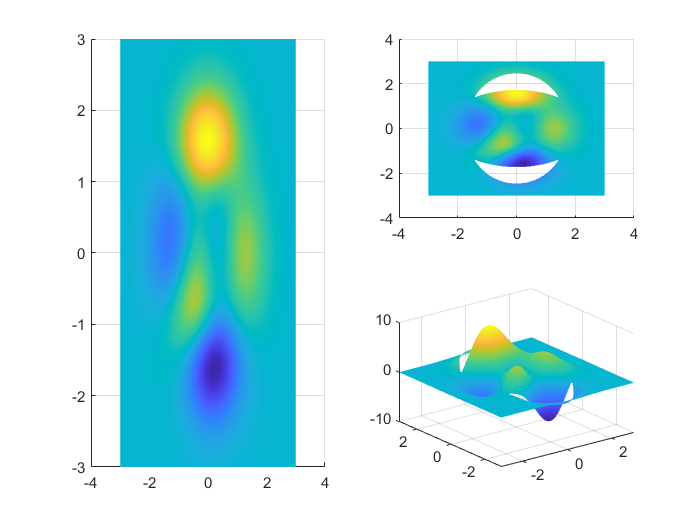

figure;
n = 300;
[x, y, z] = peaks(n);
subplot(2, 2, [1,3])
surf(x, y, z);
shading interp
view(0, 90)
for i = 1:n
    for j = 1:n
        if x(i, j)^2 + 2 * y(i, j)^2 > 6 && 2 * x(i, j)^2 + y(i, j)^2 < 6
            z(i, j) = NaN;
        end
    end
end
subplot(2, 2, 2)
surf(x, y, z);
shading interp
view(0, 90)
subplot(2, 2, 4)
surf(x, y, z);
shading interp

## 等高线图

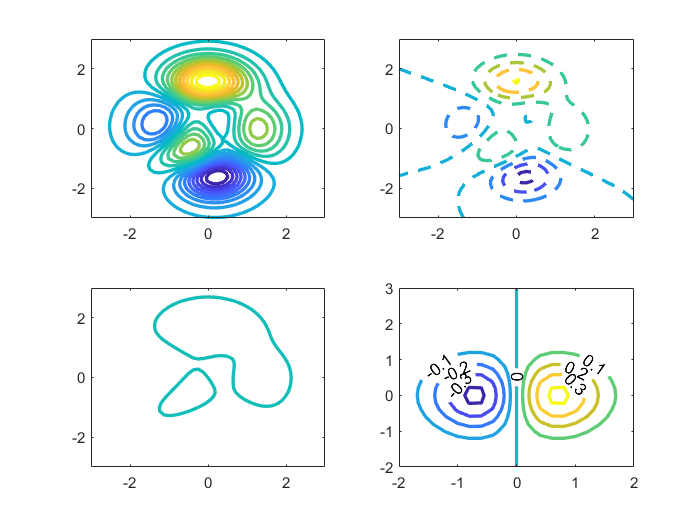

figure;
[X, Y, Z] = peaks;
subplot(2, 2, 1);
contour(X, Y, Z, 20, 'LineWidth', 2);
subplot(2, 2, 2);
contour(X, Y, Z, '--', 'LineWidth', 2)
subplot(2, 2, 3);
v = [1, 1];
contour(X, Y, Z, v, 'LineWidth', 2);
x = -2:0.2:2;
y = -2:0.2:3;
[X, Y] = meshgrid(x, y);
Z = X.*exp(-X.^2-Y.^2);
subplot(2, 2, 4);
contour(X, Y, Z, 'ShowText','on', 'LineWidth', 2);

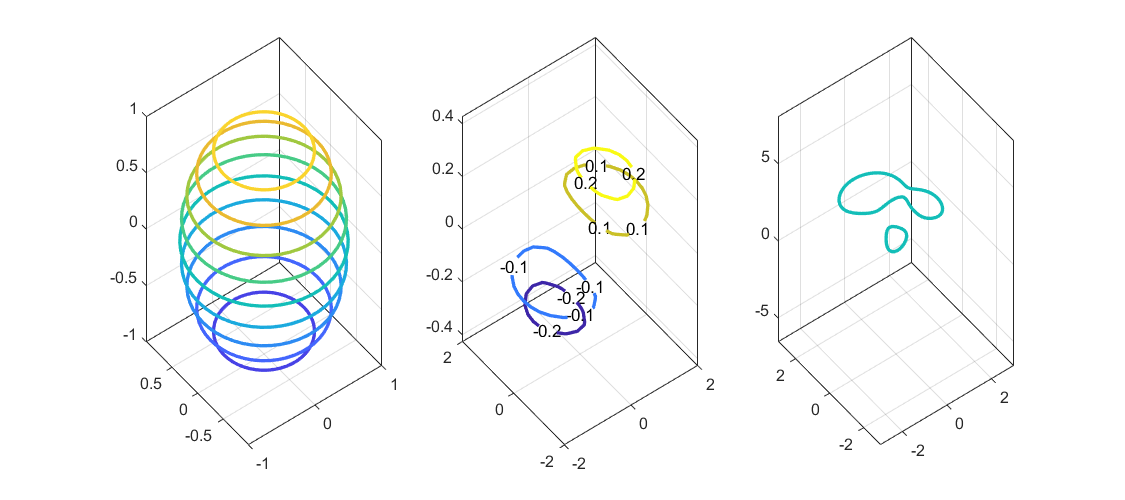

figure('Position', [0, 0, 900, 400]);
subplot(1, 3, 1);
[X, Y, Z] = sphere(50);
contour3(X, Y, Z, 'LineWidth', 2);
[X, Y] = meshgrid(-2:0.25:2);
Z = X.*exp(-X.^2-Y.^2);
subplot(1, 3, 2);
contour3(X, Y, Z, [-0.2 -0.1 0.1 0.2], 'ShowText', 'on', 'LineWidth', 2)
[X, Y, Z] = peaks;
subplot(1, 3, 3);
contour3(X, Y, Z, [2 2], 'LineWidth', 2);

## 等高线填充图

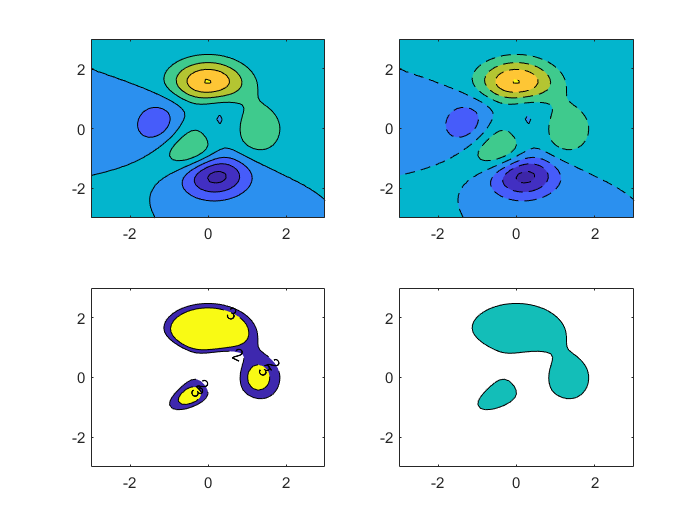

figure;
subplot(2, 2, 1);
[X, Y, Z] = peaks(50);
contourf(X, Y, Z);
subplot(2, 2, 2);
contourf(X, Y, Z,'--');
% 限定范围
subplot(2, 2, 3);
contourf(X, Y, Z, [2 3], 'ShowText', 'on');
subplot(2, 2, 4);
contourf(X, Y, Z,[2 2]);

## 三维矢量场图

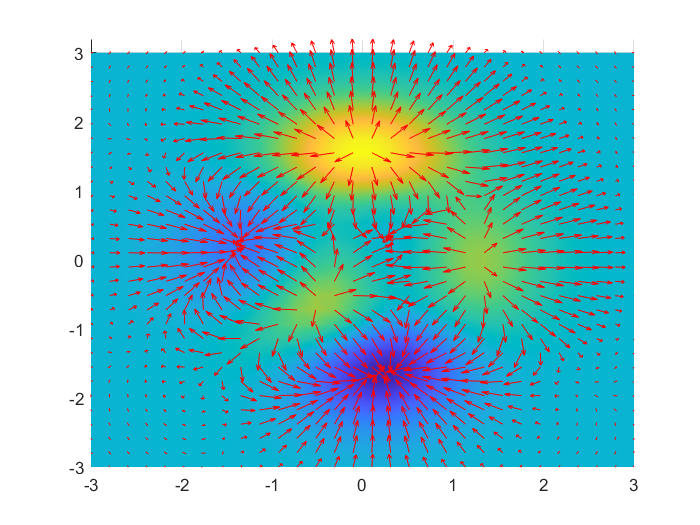

figure;
[X, Y, Z] = peaks(30);
% 矢量场，曲面法线
[U, V, W] = surfnorm(X, Y, Z);   
% 箭头长度、颜色
quiver3(X, Y, Z, U, V, W, 0.5, 'r');     
hold on
surf(X,Y,Z);  
xlim([-3, 3]);
ylim([-3, 3.2]);
shading interp
hold off
view(0, 90);